clc
clear all
format long


%%%%%%Variable declaration%%%%%%%%%%%%
%-------------------------------------------%
F_f=0.8; %non-dimensional forcing frequency
A=0.1; % non-dimensional forcing amplitude
omega=2*pi*F_f; %circular frequency

phi=0; %initial phase
t1=0; % initial time
t_run=40; %final time

j =      1


j =      2


j =      3


j =      4


j =      5


j =      6


j =      7


j =      8


j =      9


j =     10


j =     11


j =     12


j =     13


j =     14


j =     15


j =     16


j =     17


j =     18


j =     19


j =     20


j =     21


j =     22


j =     23


j =     24


j =     25


j =     26


j =     27


j =     28


j =     29


j =     30


j =     31


j =     32


j =     33


j =     34


j =     35


j =     36


j =     37


j =     38


j =     39


j =     40


j =     41


j =     42


j =     43


j =     44


j =     45


j =     46


j =     47


j =     48


j =     49


j =     50


j =     51


j =     52


j =     53


j =     54


j =     55


j =     56


j =     57


j =     58


j =     59


j =     60


j =     61


j =     62


j =     63


j =     64


j =     65


j =     66


j =     67


j =     68


j =     69


j =     70


j =     71


j =     72


j =     73


j =     74


j =     75


j =     76


j =     77


j =     78


j =     79


j =     80


j =     81


j =     82


j =     83


j =     84


j =     85


j =     86


j =     87


j =     88


j =     89


j =     90


j =     91


j =     92


j =     93


j =     94


j =     95


j =     96


j =     97


j =     98


j =     99


j =    100


j =    101


j =    102


j =    103


j =    104


j =    105


j =    106


j =    107


j =    108


j =    109


j =    110


j =    111


j =    112


j =    113


j =    114


j =    115


j =    116


j =    117


j =    118


j =    119


j =    120


j =    121


j =    122


j =    123


j =    124


j =    125


j =    126


j =    127


j =    128


j =    129


j =    130


j =    131


j =    132


j =    133


j =    134


j =    135


j =    136


j =    137


j =    138


j =    139


j =    140


j =    141


j =    142


j =    143


j =    144


j =    145


j =    146


j =    147


j =    148


j =    149


j =    150


j =    151


j =    152


j =    153


j =    154


j =    155


j =    156


j =    157


j =    158


j =    159


j =    160


j =    161


j =    162


j =    163


j =    164


j =    165


j =    166


j =    167


j =    168


j =    169


j =    170


j =    171


j =    172


j =    173


j =    174


j =    175


j =    176


j =    177


j =    178


j =    179


j =    180


j =    181


j =    182


j =    183


j =    184


j =    185


j =    186


j =    187


j =    188


j =    189


j =    190


j =    191


j =    192


j =    193


j =    194


j =    195


j =    196


j =    197


j =    198


j =    199


j =    200


j =    201


j =    202


j =    203


j =    204


j =    205


j =    206


j =    207


j =    208


j =    209


j =    210


j =    211


j =    212


j =    213


j =    214


j =    215


j =    216


j =    217


j =    218


j =    219


j =    220


j =    221


j =    222


j =    223


j =    224


j =    225


j =    226


j =    227


j =    228


j =    229


j =    230


j =    231


j =    232


j =    233


j =    234


j =    235


j =    236


j =    237


j =    238


j =    239


j =    240


j =    241


j =    242


j =    243


j =    244


j =    245


j =    246


j =    247


j =    248


j =    249


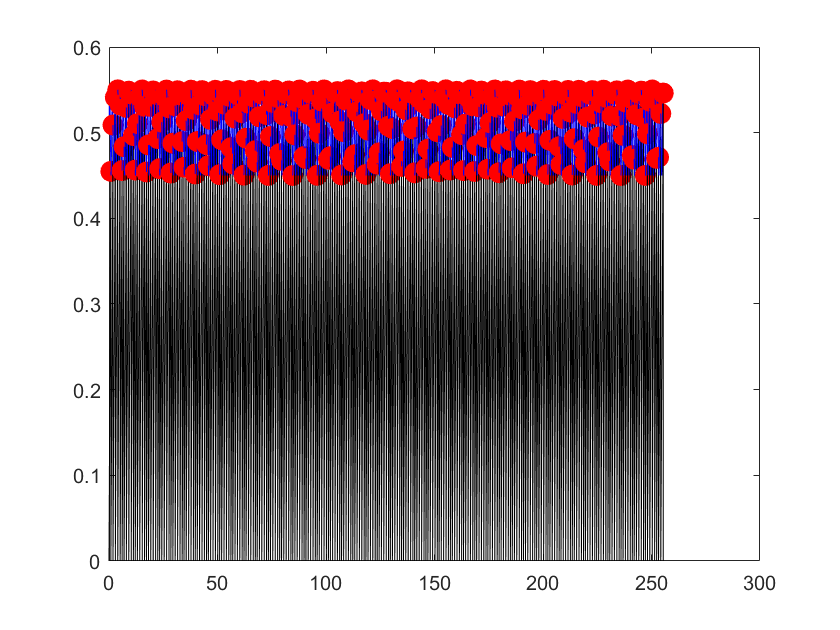

j =    250


dt=1e-5; %time step
num_vor=250; %number of vortices shed;
for j=1:num_vor
    
    tm=(t1):dt:(t1+t_run);
    for i=1:length(tm)
        tt=tm(i+1)-t1; 
        gam(i)=tt*(A^2/4+1/2)-A^2*(sin(2*omega*tm(i+1)+2*phi)-sin(2*omega*t1+2*phi))/(8*omega)+...
            A*(cos(omega*t1+phi)-cos(omega*tm(i+1)+phi))/omega; %Gamma_m
        gam_c(i)=0.5*(1+A*sin(omega*tm(i+1)+phi)); %threshold circulation Gamma_sep
        
        if gam(i)>=gam_c(i)
            gam(i+1)=0;
            tf(j)=tt; %Shedding time period
            break
        end
    end
    plot(tm(1:i),gam_c,'b',tm(1:i+1),gam(1:end),'k')
    hold on
    plot(tm(i),gam(i),'or','MarkerFaceColor','r','MarkerSize',10)
   
    clear gam gam_c
    t1=tm(i+1);  %t1=t2 condition 
    j
end

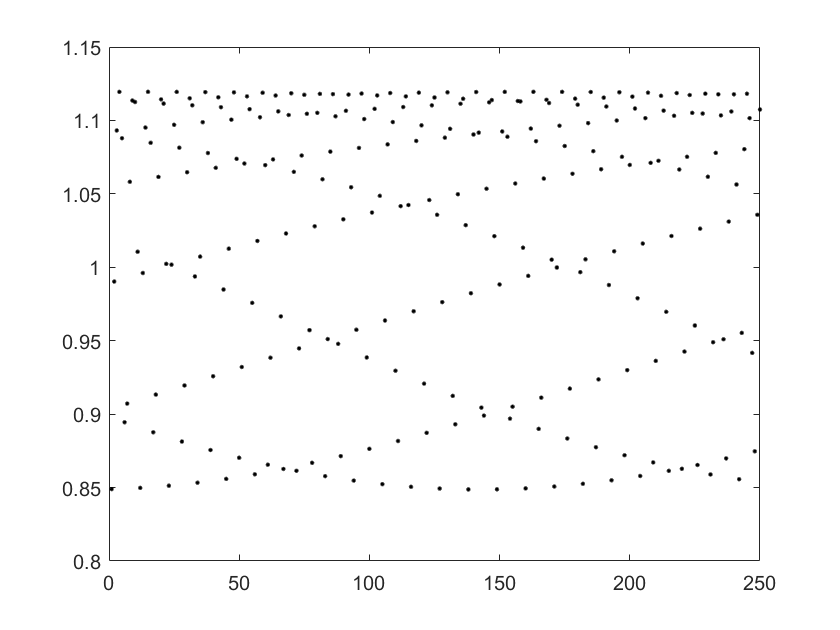

tt1=tf(end-200:end); %discard first few iterates manually
figure
plot(tf,'.k') %iterates of shedding time period 

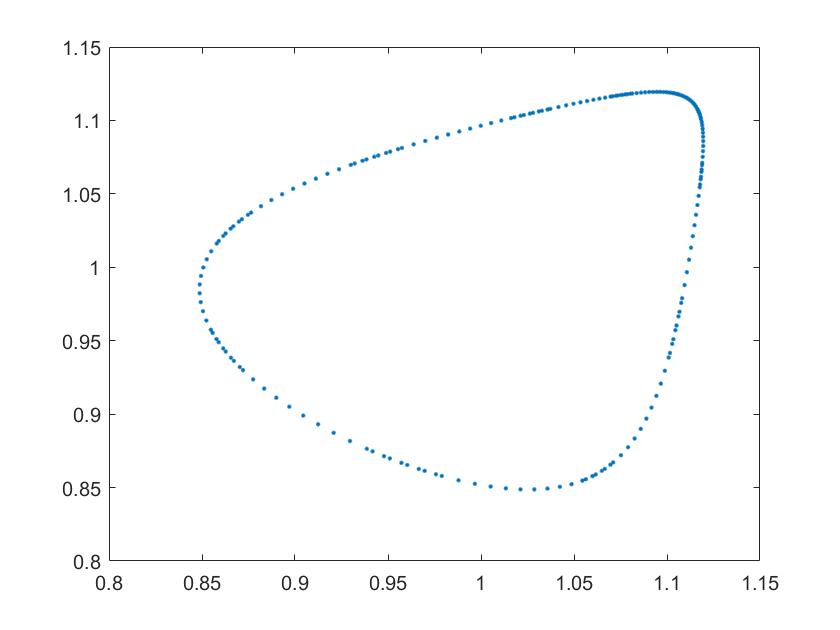

figure
plot(tt1(1:end-1),tt1(2:end),'.') %phase portrait plot